**CA1.**

# ***Please Notice:**** plots are not clear in Livescript the codes are available, consider this as my report*

`QUESTION 1.`

***In mathematics, the discrete-time Fourier transform (DTFT) is a form of Fourier analysis that is applicable to a sequence of values***

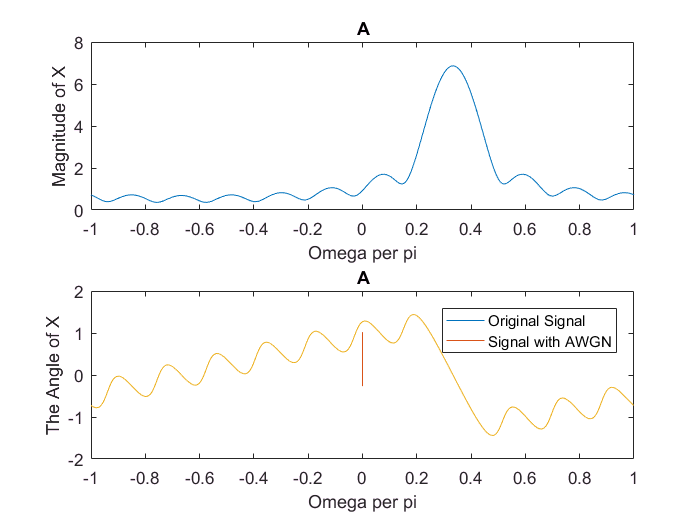

%Part__1__A__
n1=0;
n2=10;
M=800;
k = (-M:M);
Omega= (pi/M) * k;
n = (n1:n2);
%Defining our function 
x = (0.9 * exp(1i*pi/3)).^ n ; 
%Fourier Transform
X = x *  (exp(-1i*pi/M)) .^(n' *k);
%Plotting
subplot(2,1,1)
plot(Omega/pi,abs(X));
xlim([-1 1])
title('A')
xlabel('Omega per pi')
ylabel('Magnitude of X')
subplot(2,1,2)
plot(Omega/pi,angle(X));
xlim([-1 1])
title('A')
xlabel('Omega per pi')
ylabel('The Angle of X')

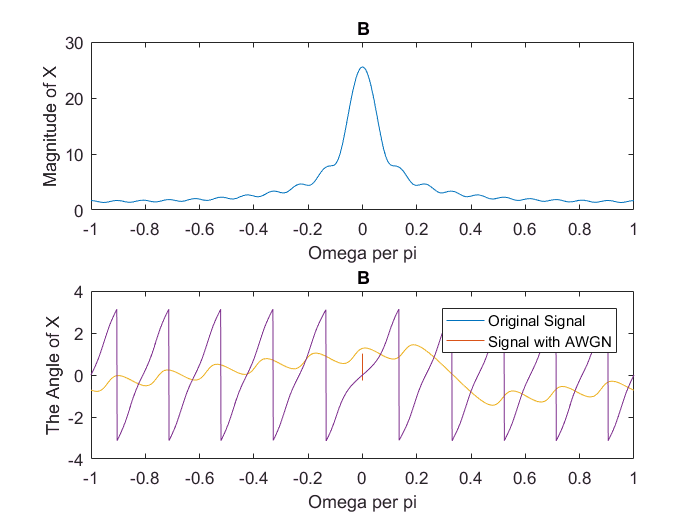

%Part__1__B__
n1=-10;
n2=10;
M=800;
k = (-M:M);
Omega= (pi/M) * k;
n = (n1:n2);
%Defining our function 
x = (0.9 ).^ n ; 
%Fourier Transform
X = x *  (exp(-1i*pi/M)) .^(n' *k);
%Plotting
subplot(2,1,1)
plot(Omega/pi,abs(X));
xlim([-1 1])
title('B')
xlabel('Omega per pi')
ylabel('Magnitude of X')
subplot(2,1,2)
plot(Omega/pi,angle(X));
xlim([-1 1])
title('B')
xlabel('Omega per pi')
ylabel('The Angle of X')

`Question.2`

***here we want to calculate the diameter of the blood vessel***

***inserting information into the matlab workspace***

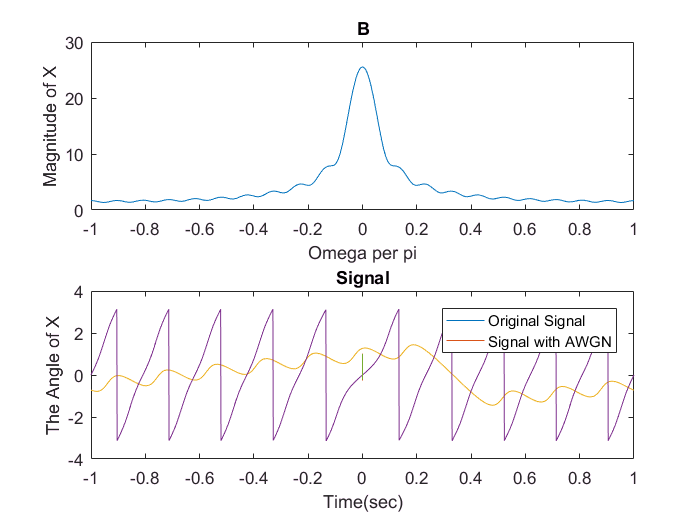

Ultra = load ('ultrasound.mat');
%Q__1__
Fsample = Ultra.data.fsample;
Signal = Ultra.data.signal ;
Time = Ultra.data.time ;
%Q__2__
plot(Time,Signal)
title('Signal')
xlabel('Time(sec)')

***Estimating blood vessel diameter***

***here the method I used for estimating the blood vessel diameter :we find the times that two peaks happened at those times and we know that at those times our ultrasound signal hit the veins.***

[Peaks_1 ,indices]  = findpeaks(Signal);
Peaks_2 = findpeaks(Peaks_1);
T_1 = indices( Peaks_1 == 1 );
T_2 = indices( Peaks_1 == 0.4 );
Delta_T = T_2 - T_1 ;
%We know that 2 * blood_vessel_diameter = velocity * Delta_T
velocity = 1540;
blood_vessel_diameter = (velocity * Delta_T)/2;

**blood_vessel_diameter   =  231000**

***here we wanna add White Gaussian Noise to our signal***

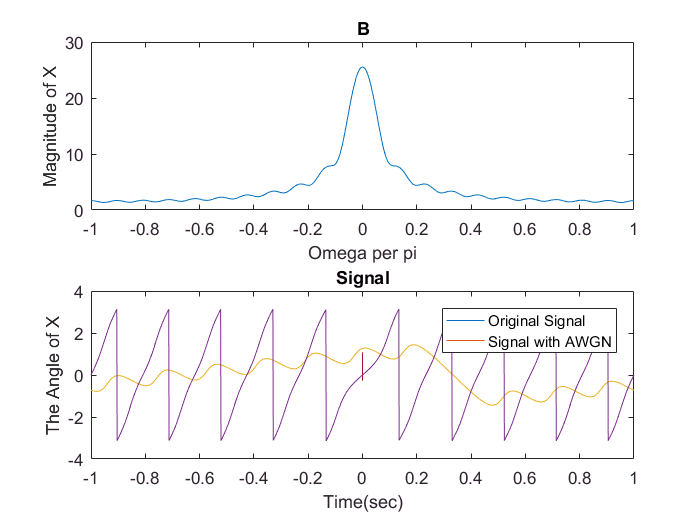

%Q__5__
Signal_With_Noise= awgn(Signal,25);
plot(Time,Signal )
hold on
plot(Time , Signal_With_Noise)
legend('Original Signal','Signal with AWGN')

%Q__6__
[Peaks_1_n ,indices_n]  = findpeaks(Signal_With_Noise);
MAX = sort(Peaks_1_n);
L =length(MAX);
T_1_n = indices_n( Peaks_1_n == MAX(L) );
T_2_n = indices_n( Peaks_1_n == MAX(L-3) );

Delta_T_n = T_2_n - T_1_n ;

%We know that 2 * blood_vessel_diameter = velocity * Delta_T

blood_vessel_diameter_noise = (velocity * Delta_T_n)/2;

** blood_vessel_diameter_noise    =  227150**

***AS we can see here because our noise is white gaussian noise and our SNR in this case is 25  ***

`Question .3`

%__(A)__
[Music , fs] = audioread('music.mp3');
%__(B)__
samples=[1,length(Music)-(5*fs)];
[Music,fs] = audioread('music.mp3',samples);
Sound = zeros(length(Music),1);
for i=1:length(Sound)
    Sound(i,1)=(Music(i,1)+Music(i,2))/2;
end

%__(C)__
fs =fs/2;
M_D = downsample(Sound,2);
M_Dec = decimate(Sound,2);

***Loosely speaking, “decimation” is the process of reducing the sampling rate.***

***In practice, this usually implies lowpass-filtering a signal,***

***then throwing away some of its samples. ***

***“Downsampling” is a more specific term which refers to just the process of throwing away samples,***

***without the lowpass filtering operation.***

y_1 = fft(M_D);
y_2 = fft(M_Dec);
z_1 = fftshift(y_1);
z_2 = fftshift(y_2);

ly_1 = length(y_1);
ly_2 = length(y_2);

f_1 = (-ly_1/2:ly_1/2-1)/ly_1*fs;
f_2 = (-ly_2/2:ly_2/2-1)/ly_2*fs;
subplot(2,1,1)
plot(f_1,abs(z_1))
xlabel 'Frequency (Hz)'
ylabel '|y_1|'
subplot(2,1,2)
plot(f_2,abs(z_2))
xlabel 'Frequency (Hz)'
ylabel '|y_2|'

%__(D)__

fs =fs * 2;
M_D = upsample(Sound,2);
M_Dec = interp(Sound,2);

***“Upsampling” is the process of inserting zero-valued samples between ***

***original samples to increase the sampling rate. ... “Interpolation”,***

***in the DSP sense, is the process of upsampling followed by filtering. ***

***(The filtering removes the undesired spectral images.)***

y_1 = fft(M_D);
y_2 = fft(M_Dec);
z_1 = fftshift(y_1);
z_2 = fftshift(y_2);

ly_1 = length(y_1);
ly_2 = length(y_2);

f_1 = (-ly_1/2:ly_1/2-1)/ly_1*fs;
f_2 = (-ly_2/2:ly_2/2-1)/ly_2*fs;

subplot(2,1,1)
plot(f_1,abs(z_1))
xlabel 'Frequency (Hz)'
ylabel '|y_1|'
subplot(2,1,2)
plot(f_2,abs(z_2))
xlabel 'Frequency (Hz)'
ylabel '|y_2|'

`Part H`

**by doubling the frequency , raising the pitch by one octave, if the tension remains the same.**

**by  using half the frequency , decreasing the pitch by one octave, if the tension remains the same.**

`Question .4`

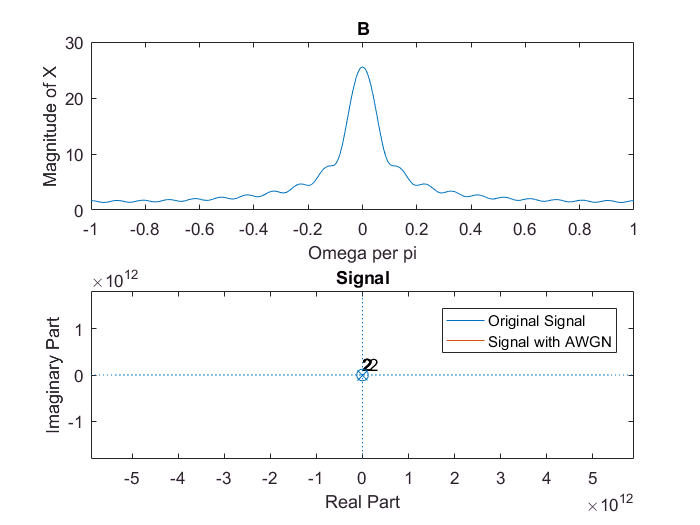

%__PART 1__
R=0.5;
W0=pi/2;
zplane([1 0 0],[1 -2*R*cos(W0) R*R]);
W0=pi/4;
zplane([1 0 0],[1 -2*R*cos(W0) R*R]);

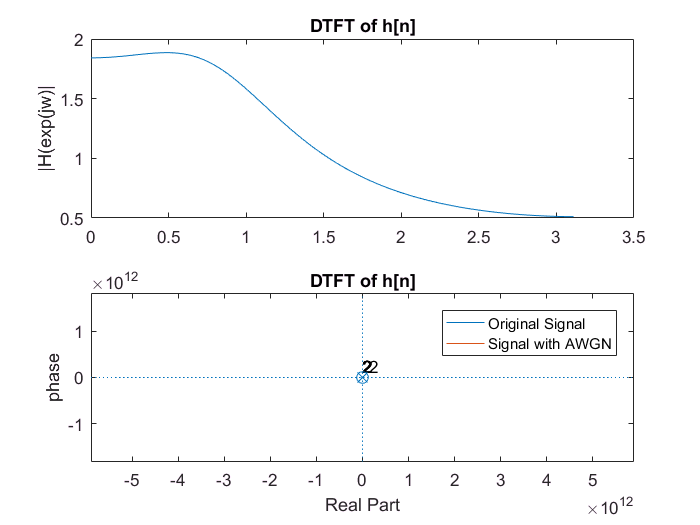

%__PART 2__
[H,w]=freqz([1 0 0],[1 -2*R*cos(W0) R*R],100);
subplot(2,1,1)
plot(w,abs(H));
title('DTFT of h[n]')  
ylabel('|H(exp(jw)|')
subplot(2,1,2)
plot(w,phase(H));
title('DTFT of h[n]')  
ylabel('phase')

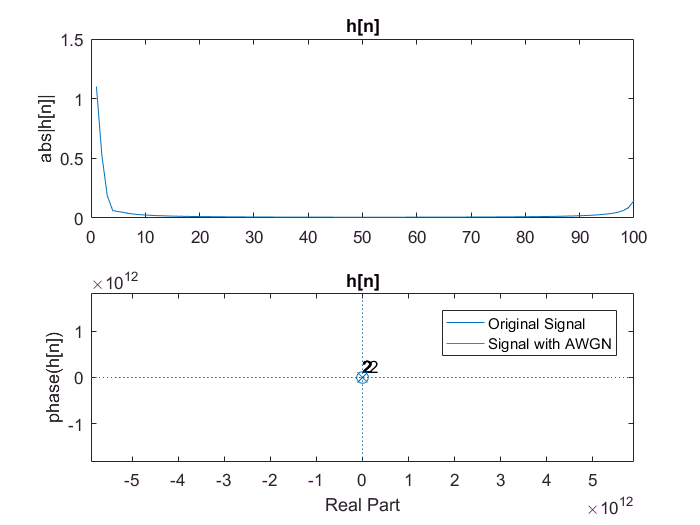

%__PART 3__
W0=pi/4;
[H_n,w]=freqz([1 0 0],[1 -2*R*cos(W0) R*R],100);
%here we wanna make the inverse fourier transform
h=ifft(H_n);
h=fftshift(h);
subplot(2,1,1)
plot(abs(h));
title('h[n]')  
ylabel('abs|h[n]|')
subplot(2,1,2)
plot(phase(h));
title('h[n]')  
ylabel('phase(h[n])')